# Thermophysical Property Prediction

Empirical regression has limitations, especially when predictions are requested outside of the training region. Physics-based information can overcome this limitation by including fundamental engineering knowledge such as constraints during the training process. Constraints can be important physics-based information to improve machine learned predictions. Constraints are demonstrated on linear regression with sample data. The purpose of this [Thermophysical Property Case Study](https://apmonitor.com/pds/index.php/Main/ThermophysicalProperties) is to evaluate the performance of a neural network with and without constraints for thermophysical property predictions.

### Linear Regression with and without Constraints

Below is an example of linear regression with and without a lower bound constraint on a parameter. In this case, the constraint is on the slope (a≥0).

% Define Data
x = rand([1 100]) + linspace(0,100);
y = rand([1 100]) + linspace(0,1);
% Linear regression model
model = fitlm(x,y)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)     0.44413     0.058392    7.6059    1.7408e-11
    x1             0.010357    0.0010013    10.343    2.1798e-17


Number of observations: 100, Error degrees of freedom: 98
Root Mean Squared Error: 0.292
R-squared: 0.522,  Adjusted R-Squared: 0.517
F-statistic vs. constant model: 107, p-value = 2.18e-17

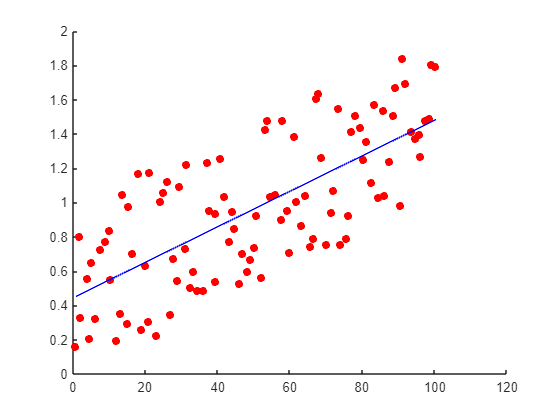

%There is a function that can do the next two lines of code. It is the After performing a linear regression using the Fit LM predict function as seen below
%coeffs = model.Coefficients.Estimate; % get coefficients
%y_predicted = coeffs(1) + coeffs(2)*x; % Calculate the corresponding y-values using the coefficients
y_predicted = predict(model, x')';

% Is it possible to make a constraint to the slope???

% Plot results
scatter(x,y,'r','filled')
hold on
plot(x,y_predicted, 'b')
hold off

### Predict Thermophysical Properties

**Background**: Parachor values are a factor in the prediction of several thermophysical properties such as surface tension and thermal conductivity. The parachor value (P) is used to predict surface tension with the difference between the density of saturated liquid ρL and saturated vapor ρV at the temperature of interest.


$$\sigma ={\left(P\left(\rho L-\rho v\right)\right)}^4$$


Surface tension and thermal conductivity are two specific properties that need improved predictions. A more accurate predictor of the parachor value (P) is an important step to improve those thermophysical properties. Most deep learning methods use a limited set of activation functions (ReLU, sigmoid, tanh, and linear) and perform unconstrained regression to minimize a loss function. The purpose of this case study is to explore the addition of physics-based information in the fitting process. This may include the use of new types of activation functions or constraints on the adjustable weights. The data for this case study is from Gharagheizi, et. al. (2011) who explored deep learning (a multi-layered neural network) to improve parachor predictions for 277 compounds from 40 functional groups.

- Name: The common chemical name

- Formula: Chemical formula of the compound

- CASN: Chemical Abstracts Service Registry Number

- Family: Chemical family of the compound

- Parachor: Estimate of parachor value

- Grp1-Grp40: Number of functional groups in the compound

**Objective**: Develop a prediction of the parachar from the chemical compound data set. Report the correlation coefficient (R2) for predicting Parachor in the test set. Randomly select values that split the data into a train (80%) and test (20%) set. Use Linear Regression and Neural Network (Deep Learning) with constraints. The solutions for regression without constraints or feature engineering are provided in this notebook. For the constrained cases, enforce a positive parachor contribution for each group. Discuss the performance of each on the train and test sets. Submit source code and a summary memo (max 2 pages) of your results.

**Load Data**

[Chemical Compound Data Set](http://apmonitor.com/pds/uploads/Main/thermo.txt)

url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt'

url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt'

**Linear Regression without Constraints**

data = readtable(url, 'VariableNamingRule', 'preserve')

data = 227×45 table
              Name               Formula          CASN                   Family               Parachor    Grp1    Grp2    Grp3    Grp4    Grp5    Grp6    Grp7    Grp8    Grp9    Grp10    Grp11    Grp12    Grp13    Grp14    Grp15    Grp16    Grp17    Grp18    Grp19    Grp20    Grp21    Grp22    Grp23    Grp24    Grp25    Grp26    Grp27    Grp28    Grp29    Grp30    Grp31

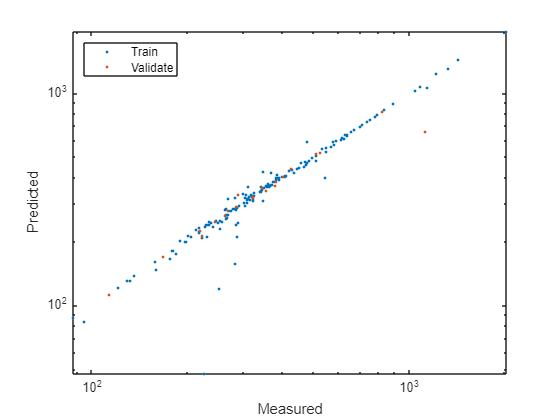

functional_group_data = data(:, 6:45); % Isolate functional group data
data_train = table2array(functional_group_data(1:205, :)); % Split functional group data into a training set
data_validate = table2array(functional_group_data(206:end, :)); % Split functional group data into a validation set
p_train = table2array(data(1:205, 5)); % Split the parachor values into a training set 
p_validate = table2array(data(206:end, 5)); % Split the parachor values into a validation set 

% Perform linar regression
model = fitlm(data_train,p_train);

% Predict parachor values
p_predicted_train = predict(model, data_train);
p_predicted_validate = predict(model, data_validate);

% Graph
loglog(p_train, p_predicted_train, '.', p_validate, p_predicted_validate, '.');
xlabel('Measured');
ylabel('Predicted');
legend('Train', 'Validate', 'Location', 'northwest');

### Neural Network (Deep Learning) without Constraints

clear;
url = 'http://apmonitor.com/pds/uploads/Main/thermo.txt';

data = readtable(url);

% Input
d = table2array(data(:, end-39:end));
x_train = d(1:205, :);
x_valid = d(206:end, :);

% Measured output
meas = data.Parachor;
y_train = meas(1:205);
y_valid = meas(206:end);

train = [x_train, y_train];
valid = [x_valid, y_valid];

% Scale training and validation data
mu_train = mean(train,1);
sigma_train = std(train,0,1);

sc_train = (train-mu_train)./sigma_train;
xs_train = sc_train(:, 1:end-1);
ys_train = sc_train(:, end);

sc_valid = (valid-mu_train)./(sigma_train);
xs_valid = sc_valid(:, 1:end-1);
ys_valid = sc_valid(:, end);

% Create neural network model
layers = [ sequenceInputLayer(40)
    fullyConnectedLayer(40)
    fullyConnectedLayer(40)
    tanhLayer()
    fullyConnectedLayer(5)
    fullyConnectedLayer(1)
    regressionLayer()
    ];

% Clarify more options for the fit
options = trainingOptions('adam', ...
    MaxEpochs=200, ...
    MiniBatchSize=100, ...
    Verbose=true, ...
    Plots='training-progress',...
    InitialLearnRate=0.001);

% Train the neural network
net = trainNetwork(xs_train',ys_train',layers,options);

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |         1.40 |          1.0 |          0.0010 |
|      50 |          50 |       00:00:07 |         0.20 |      2.1e-02 |          0.0010 |
|     100 |         100 |       00:00:08 |         0.15 |      1.1e-02 |          0.0010 |
|     150 |         150 |       00:00:09 |         0.13 |      8.3e-03 |          0.0010 |
|     200 |         200 |       00:00:11 |         0.11 |      6.3e-03 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.



% Test the model on training data
Y1P = predict(net, xs_train');
mse_train = mean((ys_train' - Y1P).^2);
fprintf('Mean Squared Error (Train): %.4f\n', mse_train);

Mean Squared Error (Train): 0.0126



% Test the model on validation data
Y2P = predict(net, xs_valid');
mse_valid = mean((ys_valid' - Y2P).^2);
fprintf('Mean Squared Error (Valid): %.4f\n', mse_valid);

Mean Squared Error (Valid): 0.2235


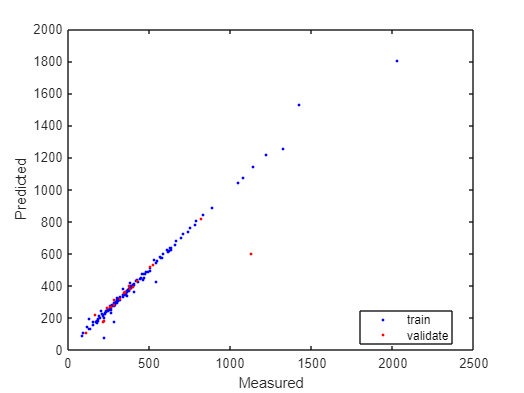

Error using gekko>solve
Python Error: Exception:  @error: Model Expression
 *** Error in syntax of function string: Missing operator
 
Position: 18                  
 0.682457664450218,0.33792251077998015,0.9465227295578098,0.02338023515012816,0.16949780555361965,0.7103365143049047,-0.036789017334035834,0.38983982232771563,0.6390068175317886,0.5570050601028818,-0.060357221717743076,0.2156720356828007,0.10795612998922677,0.21587123457142687,0.30457511729581116,-0.15722460781078168,0.5820982840120406,0.2967599048978786,-0.2006967921956938,0.1820722071632735,0.5275757329367907,0.3588594594422068,0.24124269253454433,0.0015728203362775917,-0.22453038918195523,0.06421766602651402,-0.2764818623644485,-0.22615295393364843,0.34514566656037493,0.2993614551358247,0.18852881810524602,0.2995471809042508,-0.4676246956887685,-0.1491255184302015,-0.059863370459377396,0.20611163883019734


% Unscale for plotting and analysis
Y1u = ys_train * sigma_train(end) + mu_train(end);
Y1Pu = Y1P * sigma_train(end) + mu_train(end);

Y2u = ys_valid * sigma_train(end) + mu_train(end);
Y2Pu = Y2P * sigma_train(end) + mu_train(end);

% Plot Measured vs Predicted
figure;
plot(Y1u, Y1Pu, 'b.', 'DisplayName', 'train');
hold on;
plot(Y2u, Y2Pu, 'r.', 'DisplayName', 'validate');
xlabel('Measured');
ylabel('Predicted');
legend('Location', 'best');